## Regresión Lineal de NDVI del año 2022, cuenca del Río Pánuco

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Filtrado de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla

tmp =  find(  info_hdf.anio == 2022 );
info_consulta = info_hdf(tmp,:);

[filas,~] = size(info_consulta);
disp("Num de imágenes: "+filas);

Num de imágenes: 23


### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 2d para el promedio por día
arr_promedio_dia = zeros(1,filas);


Recuperar  la información

Obteniendo información:  1 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"       -1  
    499     33

Obteniendo información:  2 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  3 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  4 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  5 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  6 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  7 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  8 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  9 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  10 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  11 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  12 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  13 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  14 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  15 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  16 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  17 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  18 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  19 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  20 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  21 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  22 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

Obteniendo información:  23 de 23


info_consulta = 23×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

    497      1      1      1        4        2022    "MOD13A2.A2022001.h08v06.061.2022018201103.hdf"    "MOD13A2.A2022001.h08v07.061.2022018162820.hdf"      100  
    498     17     17      1        4        2022    "MOD13A2.A2022017.h08v06.061.2022034232245.hdf"    "MOD13A2.A2022017.h08v07.061.2022035002112.hdf"      100  
    499     33

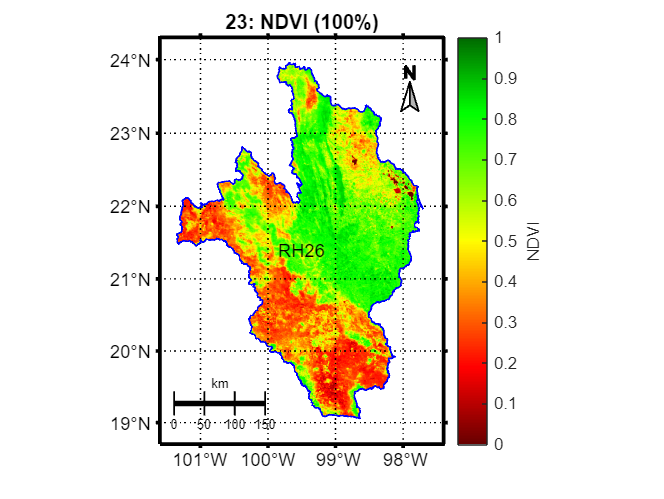

for i=1:filas
    disp("Obteniendo información:  "+i+" de "+filas);
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %quitar las nubes y nieve y demas pixeles anomalos
    ndvi (disponibilidad>1 & disponibilidad < 0)=NaN;
    
    %obtener la calidad y almacenarla en el campo correspondiente
    tmp_calidad = m_calidad_imagen(disponibilidad,calidad_total);
    info_consulta.Calidad(i) = tmp_calidad

    if (tmp_calidad >= 95)
        % promedio ndvi 
        arr_promedio_dia(i) = mean(ndvi,'all','omitnan');
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = ndvi;
    else
        % promedio ndvi 
        arr_promedio_dia(i) = nan;
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = nan;
    end

    % si se desea, mostrar cada imagen individual
    if debug_dibujar_mapa == true 
        m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,i+": NDVI ("+tmp_calidad+"%)",[0 1],ndvi_colormap,"NDVI");
        m_dibujar_kml(dir_data,"RH26",1,'b',"RH26");
        pause(debug_pausa);
    end
end

### 4.- Usar los datos obtenidos 

Mostrar el promedio por día de NDVI 

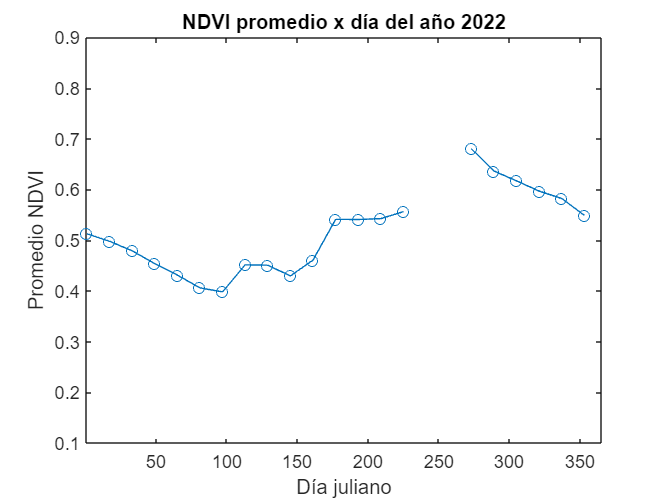

tmp_dias = table2array(info_consulta(:,"diaj"));
figure
plot(tmp_dias,arr_promedio_dia,'-o');
xlim([1 365]);
ylim([0.1 0.9]);
title('NDVI promedio x día del año 2022')
xlabel('Día juliano')
ylabel('Promedio NDVI')

Mostrar mapa del promedio por pixel del periodo de estudio 2022

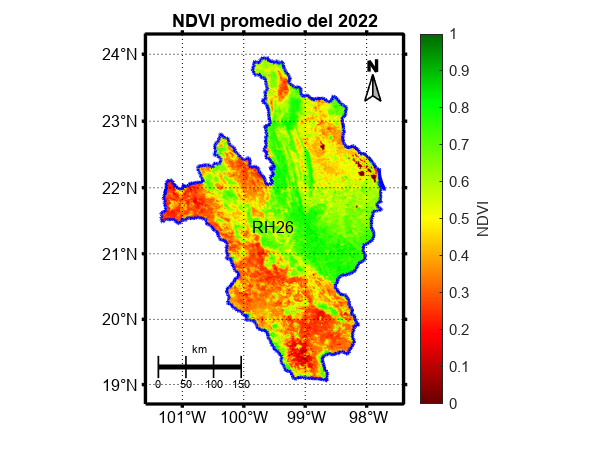

m1 = m_mean_3dpp(arr_ndvi);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1,"NDVI promedio del 2022",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",2,"b","RH26");